# AXIAL TURBINE ANALYSIS - sCO_2 

## Pre-set parameters

% WHOLE cycle is in supercritical region.
W_t_goal = 1e3  % kW, Turbine output

W_t_goal = 1000

ef_c = 0.80;    % Compressor is.efficiency
ef_t = 0.85;    % Turbine is.efficiency
g = 9.81;       % Gravity acceleration, in m/s^2

## Supercritical CO2 Cycle

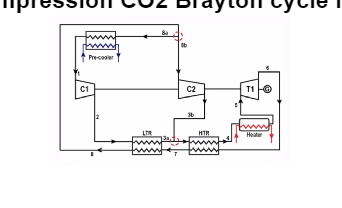

% File path of the image
filePath = 'SC_CO2.jpg'; % Change this to the actual path of your image

% Read the image
imageData = imread(filePath);

% Display the image
imshow(imageData);
title('Recompression CO2 Brayton cycle layout');

## REFPROP - Main Parameters

% Pressure [Mpa]
P1 = 7.8;
P2 = 20;
P3 = P2;
P4 = P2;
P5 = P2;
P6 = P1;
P7 = P1;
P8 = P1;
P9 = P1;

T1 = 307.5;  % Chose its value to be just above the critical point.
%--------------------------------------------------------------------------------------------
h1 = refpropm('H','T',T1,'P',P1*1e3,'co2')/1e3

refpropm is not found in the current folder or on the MATLAB path, but exists in:
    C:\Program Files\MATLAB\R2024b

Change the MATLAB current folder or add its folder to the MATLAB path.


s1_s = refpropm('S','T',T1,'P',P1*1e3,'co2');
s2_s = s1_s;

h2_s = refpropm('H','P',P2*1e3,'S',s2_s,'co2')/1e3

w_c1_s = h2_s-h1
w_c1 = w_c1_s*ef_c

h2 = w_c1+h1
%--------------------------------------------------------------------------------------------
T2 = refpropm('T','H',h2*1e3,'P',P2*1e3,'co2')
%--------------------------------------------------------------------------------------------
T8 = 380;
h8 = refpropm('H','T',T8,'P',P8*1e3,'co2')/1e3

s8_s = refpropm('S','T',T8,'P',P8*1e3,'co2'); %J/kg
s3_s = s8_s; %J/kg

h3_s = refpropm('H','P',P3*1e3,'S',s3_s,'co2')/1e3

w_c2_s = h3_s-h8
w_c2 = w_c2_s*ef_c

h3 = w_c2+h8
T3 = refpropm('T','H',h3*1e3,'P',P3*1e3,'co2')
%------------------------------------------------------------------------
T4 = 658.8;  % Predifined value from article.
T5 = 823  %823.15; % Expected inlet temperature for a turbine.
%------------------------------------------------------------------------
h5 = refpropm('H','T',T5,'P',P5*1e3,'co2')/1e3

s5_s = refpropm('S','T',T5,'P',P5*1e3,'co2');
s6_s = s5_s;

h6_s = refpropm('H','P',P6*1e3,'S',s6_s,'co2')/1e3

w_t_s = h5-h6_s
w_t = w_t_s*ef_t

h6 = h5-w_t
%------------------------------------------------------------------------
T6 = refpropm('T','H',h6*1e3,'P',P6*1e3,'co2')
T7 = 491.86; % Predifined value from article.
T9 = T1;

% Enthalpy [kJ/kg]
h3 = refpropm('H','T',T3,'P',P3*1e3,'co2')/1e3;
h4 = refpropm('H','T',T4,'P',P4*1e3,'co2')/1e3;

h7 = refpropm('H','T',T7,'P',P7*1e3,'co2')/1e3;

h9 = refpropm('H','T',T9,'P',P9*1e3,'co2')/1e3;

% Density [kg/m3]
rho1 = refpropm('D','T',T1,'P',P1*1e3,'co2');
rho2 = refpropm('D','T',T2,'P',P2*1e3,'co2');
rho3 = refpropm('D','T',T3,'P',P3*1e3,'co2');
rho4 = refpropm('D','T',T4,'P',P4*1e3,'co2');
rho5 = refpropm('D','T',T5,'P',P5*1e3,'co2')
rho6 = refpropm('D','T',T6,'P',P6*1e3,'co2')
rho7 = refpropm('D','T',T7,'P',P7*1e3,'co2');
rho8 = refpropm('D','T',T8,'P',P8*1e3,'co2');
rho9 = refpropm('D','T',T9,'P',P9*1e3,'co2');

% Entropy [J/kgK]
s1 = refpropm('S','T',T1,'P',P1*1e3,'co2');
s2 = refpropm('S','T',T2,'P',P2*1e3,'co2');
s3 = refpropm('S','T',T3,'P',P3*1e3,'co2');
s4 = refpropm('S','T',T4,'P',P4*1e3,'co2');
s5 = refpropm('S','T',T5,'P',P5*1e3,'co2');
s6 = refpropm('S','T',T6,'P',P6*1e3,'co2');
s7 = refpropm('S','T',T7,'P',P7*1e3,'co2');
s8 = refpropm('S','T',T8,'P',P8*1e3,'co2');
s9 = refpropm('S','T',T9,'P',P9*1e3,'co2');

## Arrays of Main Parameters

P = [P1,P2,P3,P4,P5,P6,P7,P8,P9];
T = [T1,T2,T3,T4,T5,T6,T7,T8,T9];
h = [h1,h2,h3,h4,h5,h6,h7,h8,h9];
s = [s1,s2,s3,s4,s5,s6,s7,s8,s9];
rho = [rho1,rho2,rho3,rho4,rho5,rho6,rho7,rho8,rho9];

## Plot P-h Diagram

figure;
set(gcf,'Units','centimeters','Position',[3 3 30 21]);

plotPh_Sara();

P_h = plot(h,P*10,'m','MarkerSize',10,'DisplayName','Work Cycle','LineWidth',1);

a1 = plot(h1,P1*10,'s','color','m','MarkerSize',10,'DisplayName','1^{st} Compressor');
a2 = plot(h2,P2*10,'o','color','m','MarkerSize',10,'DisplayName','LTR');
a3 = plot(h3,P3*10,'>','color','m','MarkerSize',10,'DisplayName','HTR');
a4 = plot(h4,P4*10,'p','color','m','MarkerSize',10,'DisplayName','Heater');
a5 = plot(h5,P5*10,'^','color','m','MarkerSize',10,'DisplayName','Turbine');
a6 = plot(h6,P6*10,'o','color','m','MarkerSize',10,'DisplayName','HTR');
a7 = plot(h7,P7*10,'<','color','m','MarkerSize',10,'DisplayName','LTR');
a8 = plot(h8,P8*10,'*','color','m','MarkerSize',10,'DisplayName','Pre-Cooler/2^{nd} Compressor');
a9 = plot(h9,P9*10,'s','color','m','MarkerSize',10,'HandleVisibility','off');

title('Pressure-Enthalpy (P-h) Diagram of CO_{2}')

xlim([100 1100]);
xticks(100:100:1100)
ylim([0 260]);

## Plot T-s Diagram

figure;
set(gcf,'Units','centimeters','Position',[3 3 30 21]);

plotTs_Sara();

T_s = plot(s,T,'b','MarkerSize',10,'DisplayName','Work Cycle','LineWidth',1);
hold on;

b1 = plot(s1,T1,'s','color','b','MarkerSize',10,'DisplayName','1^{st} Compressor');
b2 = plot(s2,T2,'o','color','b','MarkerSize',10,'DisplayName','LTR');
b3 = plot(s3,T3,'>','color','b','MarkerSize',10,'DisplayName','HTR');
b4 = plot(s4,T4,'p','color','b','MarkerSize',10,'DisplayName','Heater');
b5 = plot(s5,T5,'^','color','b','MarkerSize',10,'DisplayName','Turbine');
b6 = plot(s6,T6,'o','color','b','MarkerSize',10,'DisplayName','HTR');
b7 = plot(s7,T7,'<','color','b','MarkerSize',10,'DisplayName','LTR');
b8 = plot(s8,T8,'*','color','b','MarkerSize',10,'DisplayName','Pre-Cooler/2^{nd} Compressor');
b9 = plot(s9,T9,'s','color','b','MarkerSize',10,'HandleVisibility','off');

xlim([500 3000]);
xticks(500:500:3000)
ylim([220 860]);
yticks(220:80:860);
  
colormap('turbo');
clim([200,860]);

grid on;

xlabel('Entropy (J/(kg*K)');
ylabel('Temperature (K)');

title('Temperature-Entropy (T-s) Diagram of CO_{2}');


## Plot h-s Diagram

figure;
set(gcf,'Units','centimeters','Position',[3 3 30 21]);

h_s = plot(s,h,'g','MarkerSize',10,'DisplayName','Work Cycle','LineWidth',1.5);
hold on;

y1 = plot(s1,h1,'s','color','g','MarkerSize',10,'DisplayName','1^{st} Compressor');
y2 = plot(s2,h2,'o','color','g','MarkerSize',10,'DisplayName','LTR');
y3 = plot(s3,h3,'>','color','g','MarkerSize',10,'DisplayName','HTR');
y4 = plot(s4,h4,'p','color','g','MarkerSize',10,'DisplayName','Heater');
y5 = plot(s5,h5,'^','color','g','MarkerSize',10,'DisplayName','Turbine');
y6 = plot(s6,h6,'o','color','g','MarkerSize',10,'DisplayName','HTR');
y7 = plot(s7,h7,'<','color','g','MarkerSize',10,'DisplayName','LTR');
y8 = plot(s8,h8,'*','color','g','MarkerSize',10,'DisplayName','Pre-Cooler/2^{nd} Compressor');
y9 = plot(s9,h9,'s','color','g','MarkerSize',10,'HandleVisibility','off');

xlim([1250 3000]);
xticks(1250:250:3000)
ylim([200 1200]);
yticks(200:200:1200);
  
colormap('turbo');
clim([200,900]);

grid on;

xlabel('Entropy (kJ/(kg*K))');
ylabel('Enthalpy (kJ/kg)');

title('Enthalpy-Entropy (h-s) Diagram of CO_{2}');
legend('show', 'Location', 'southeast');

## Mass - Volume of CO2

D_h = abs(h6-h5) % kJ/kg

% Mass flow rates (kg/s)
m_dot = W_t_goal/w_t % total MF based on the desired kW

y_m = 1-((h8-h7)/(h2-h3)) % απο ισολογισμό ενέργειας LTR, (1-y)m(h2-h3)=m(h8-h7)
m1_dot = (1-y_m)*m_dot
m2_dot = y_m*m_dot

% Volumetric flow [m3/s]
V1 = m_dot/rho1;
V2 = m_dot/rho2;
V3 = m_dot/rho3;
V4 = m_dot/rho4;
V5 = m_dot/rho5;
V6 = m_dot/rho6;
V7 = m_dot/rho7;
V8 = m_dot/rho8;
V9 = m_dot/rho9;

V = [V1,V2,V3,V4,V5,V6,V7,V8];

## Effectiveness of Recuperators

% HTR
epsilon_HTR = (h4-h3)/(h6-h3)

% LTR
epsilon_LTR = (m1_dot*(h3-h2))/(m_dot*(h7-h2))

## Work Production/Consumtion

% In kW
W_tur = m_dot*w_t % όντως W_goal

W_com1 = m1_dot*w_c1
W_com2 = m2_dot*w_c2

Q_ltr = m1_dot*abs(h3-h2)-m_dot*abs(h8-h7)
Q_htr = m_dot*abs(h4-h3)-abs(h7-h6)

Q_heater = m_dot*(h5-h4)
Q_cooler = m1_dot*(h1-h8)

% Final
ef_mech = 0.9 % μηχανική απόδοση

W_NET = ef_mech*W_tur - (W_com1+W_com2)/ef_mech
Q_TOTAL = Q_ltr + Q_htr + Q_heater + Q_cooler

% Electricity Production
ef_gen = 0.95 % ηλεκτρική απόδοση γεννήτριας
P_gen = ef_gen*W_NET % kWe

% Thermal efficincy of cycle
ef_th = W_NET/Q_heater % Qheater γτ στην ουσία αυτός είναι ο reactor

## Preliminary design

% Ns and Ds from *Balje diagram* (απόδοση ~0.8-0.9)
Ns = 0.4;
Ds = 4.65;

rho_avrg = (rho5+rho6)/2 %average of inlet and outlet

% Calculation of rotational speed (Ω) and tip diameter (Dt)
Dt = ((Ds*((m_dot/rho_avrg)^0.5))/((D_h*1e3)^0.25)) %m
Dt_mm = Dt*1e3

omega = (Ns*((D_h*1e3)^0.75))/((m_dot/rho_avrg)^0.5) %rad/s
omega_RPS = ceil(omega/(2*pi))
omega_RPM = ceil((omega*60)/(2*pi))

## Initial Geometrical Parameters

hub_tip_ratio = 0.8; %σημειώσεις διάλεξης σελ.14

rt = Dt/2 %m
rh = hub_tip_ratio*rt %m

rm = (rt+rh)/2 %m

Dh = 2*rh %m
Dm = 2*rm %m
% "New efficiency charts for the optimum design of axial flow turbines"

At = pi*(rt^2) %m2
Ah = pi*(rh^2) %m2
A = At-Ah %Χρήσιμο εμβαδόν (m2)

## Turbine Velocity Triangles (rm)

% STATOR
%------------------------------------------------------------------------
% INLET

% In kJ/kg
h_01 = h5

h_02 = h_01

h_03 = h6
h_03_s = h6_s

c_x = m_dot/(rho5*A) %m/s, inlet absolute velocity (Dixon)

U = (omega)*(rm) %m/s, blade velocity

phi = c_x/U %peripou 0-0.4
psi = (D_h*1e3)/(U^2) %peripou 1-2.5

alpha_1_deg = 15 %Inlet stator angle (degree)
alpha_1_rad = alpha_1_deg*(pi/180);

c_1 = c_x/cos(alpha_1_rad) %m/s

% ROTOR
%------------------------------------------------------------------------
%INLET
R = 1 - (0.5*psi)+(phi*tan(alpha_1_rad))

alpha_2_rad = atan((2*(1-R)/phi)+tan(alpha_1_rad)); %Dixon: R=1-f/2(tana2-tana1)
alpha_2_deg = alpha_2_rad*(180/pi)

c_2 = c_x/cos(alpha_2_rad)
c_th_2 = c_x*(tan(alpha_2_rad))

beta_2_rad = atan((1/(2*phi))*((0.5*psi)-(2*R)));
beta_2_deg = beta_2_rad*(180/pi) % R<0.5 then β2<α1

w_th_2 = c_th_2-U
w_2 = sqrt((c_x^2)+(w_th_2^2))

%------------------------------------------------------------------------
%OUTLET
beta_3_rad = atan((1/(2*phi))*((0.5*psi)+(2*R)));
beta_3_deg = beta_3_rad*(180/pi)

alpha_3_rad = atan(tan(beta_3_rad)-(1/phi));
alpha_3_deg = alpha_3_rad*(180/pi)

c_3 = c_x/cos(alpha_3_rad) %m/s
c_th_3 = sqrt((c_3^2)-(c_x^2)) %m/s

w_th_3 = c_th_3+U %m/s, παρουσίαση γκούντα σελ.5
w_3 = sqrt((c_x^2)+(w_th_3^2)) %m/s
%------------------------------------------------------------------------

zeta_s = (alpha_1_deg+alpha_2_deg)/2 % stagger angle
delta_s = 4 % deviation angle (I chose it to be as small as realistically possible)
theta_s = alpha_1_deg-alpha_2_deg % camber angle
iota_s = 0 % incidence angle

zeta_r = (beta_3_deg+beta_2_deg)/2 % stagger angle
delta_r = 2 % deviation angle (I chose it to be as small as realistically possible)
theta_r = beta_2_deg-beta_3_deg % camber angle
iota_r = beta_3_deg-zeta_r % incidence angle


## Velocity Triangles Drawing

% Create figure
figure;
hold on;
axis equal;
grid on;

% Plot the inlet velocity triangle (swapping x and y coordinates, inverting y)
quiver(0, 0, c_th_2, -c_x, 'r', 'DisplayName', 'Absolute');
quiver(0, 0, w_th_2, -c_x, 'g', 'DisplayName', 'Relative');
quiver(w_th_2-12, -c_x+4, U, 0, 'b', 'DisplayName', 'Angular');

% Plot the outlet velocity triangle (swapping x and y coordinates, inverting y)
quiver(c_x+w_th_2+U, 0, -w_th_3, -c_x, 'g', 'HandleVisibility', 'off');
quiver(c_x+w_th_2+U, 0, -c_th_3, -c_x, 'r', 'HandleVisibility', 'off');

% Labels and legend
xlabel('Radial Velocity (m/s)');
ylabel('Axial Velocity (m/s)');
title('Velocity Triangles of 1MW sCO_2 Axial Turbine');
legend('show','Location','northeast');

% Additional annotations (swapping x and y coordinates, inverting y)
text(U+w_th_2, -c_x/2, 'C_3', 'FontSize', 12, 'Color', 'r');
text(c_x+U/2, -1.1*c_x, 'U', 'FontSize', 12, 'Color', 'b');
text(w_th_2/2, -c_x/6, 'W_2', 'FontSize', 12, 'Color', 'g');
text(c_th_2/4, c_x/6, 'C_2', 'FontSize', 12, 'Color', 'r');
text(w_th_3, c_x/6, 'W_3', 'FontSize', 12, 'Color', 'g');

xlim([0 450]);
xticks(0:50:450)
ylim([-100 100]);
yticks(-100:25:100)

hold off;

## Total/Static Pressures

% Total (MPa)
P_01 = P5
P_03 = P6

% Static (MPa)
P_1 = P_01-((0.5*rho5*(c_1^2))/1e6) % Τις ολικές πιέσεις επι 1e-6 γτ Pa->MPa
P_3 = P_03-((0.5*rho6*(c_3^2))/1e6)
P_2 = R*(P_1-P_3)+P_3

P_02 = P_2+((0.5*rho6*(c_2^2))/1e6)

P_02_rel = P_2+((0.5*rho_avrg*(w_2^2))/1e6)
P_03_rel = P_3+((0.5*rho6*(w_3^2))/1e6)

## Static Enthalpies/Temperatures

% In kJ/kg
h_1 = ((h_01*1e3)-(0.5*(c_1^2)))/1e3

h_2 = ((h_02*1e3)-(0.5*(c_2^2)))/1e3

h_3 = ((h_03*1e3)-(0.5*(c_3^2)))/1e3
h_3s = ((h_03_s*1e3)-(0.5*(c_3^2)))/1e3

% In kJ/kgK
Cp_01 = refpropm('C','H',h_01*1e3,'P',P_01*1e3,'co2')/1e3
Cp_02 = refpropm('C','H',h_02*1e3,'P',P_02*1e3,'co2')/1e3
Cp_03 = refpropm('C','H',h_03*1e3,'P',P_03*1e3,'co2')/1e3

% In K
T_01 = h_01/Cp_01
T_02 = h_02/Cp_02
T_03 = h_03/Cp_03
T_03s = refpropm('T','H',h_03_s*1e3,'P',P_03*1e3,'co2')

% In kJ/kgK
Cp_1 = refpropm('C','H',h_1*1e3,'P',P_1*1e3,'co2')/1e3
Cp_2 = refpropm('C','H',h_2*1e3,'P',P_2*1e3,'co2')/1e3
Cp_3 = refpropm('C','H',h_3*1e3,'P',P_3*1e3,'co2')/1e3

% In K
T_1 = h_1/Cp_1
T_2 = h_2/Cp_2
T_3 = h_3/Cp_3
T_3s = refpropm('T','H',h_3s*1e3,'P',P_3*1e3,'co2')

s01 = s5;

s02_s = refpropm('S','T',T_01,'P',P_01*1e3,'co2')
h_02_s = refpropm('H','P',P_02*1e3,'S',s02_s,'co2')/1e3
h_2s = ((h_02_s*1e3)-(0.5*(c_2^2)))/1e3
T_2s = refpropm('T','H',h_2s*1e3,'P',P_2*1e3,'co2')

s03 = s6;

s02 = refpropm('S','T',T_02,'P',P_02*1e3,'co2')
s03_ss = s02;
T_3ss = refpropm('T','P',P_3*1e3,'S',s03_ss,'co2')

% rothalpy (kJ/kg)
I_02 = h_2 + (w_2^2)/(2e3) - (U^2)/(2e3) % =I3, rothalpy preserved in rotor

## Efficiencies

% Total-to-total
ita_tt = (h_01-h_03)/(h_01-h_03_s)

% Total-to-static
ita_ts = (h_01-h_03)/(h_01-h_3)

## Various Turbine Coefficients

VR = V6/V5 % volumetric expansion ratio

DR = rho6/rho5 % density ratio

PR = P2/P1 % pressure expansion ratio

% SP = sqrt(V6)/((h_01-h_03)^0.25)
% Τα παραπάνω είναι απο το "New efficiency charts for the optimum design of axial flow turbines"

%------------------------------------------------------------------------
%Add = tan(alpha_2_rad)+tan(beta_3_rad) % Για χρήση στο διάγραμα στις διαφάνειες του Γκούντα 
%------------------------------------------------------------------------

## Geometry

h_b = rt-rh %Blade height (m)
w_b = h_b/2 %Height/width ratio = 2-3

h_D_ratio = h_b/Dt

aspect_ratio = 0.7; %το θέτω εγω απο βιβλιογραφία, >1
cord = h_b/aspect_ratio %m

%------------------------------------------------------------------------
% For simulation
L_in_s = 10*cord*1e3 %mm
L_out_s = 0.5*cord*1e3

L_in_r = 0.5*cord*1e3
L_out_r = 10*cord*1e3
%------------------------------------------------------------------------

thickness_cord_ratio = 0.2;
t_b = cord*thickness_cord_ratio %m
t_b_mm = t_b*1e3

p_c_ratio = 0.8/((2*cos(alpha_2_rad))*(tan(alpha_1_rad)+tan(alpha_2_rad))) % pitch-cord ratio
pitch = cord*p_c_ratio %m

tip_clearance = 0.0001; %m   0-0.0025

N_b = ceil((2*pi*rm)/pitch) %Number of blades

%delta_s = 0.3*thickness_cord_ratio*(1-(cos(alpha_1_rad+alpha_2_rad))/2)*(180/pi)
%delta_r = 0.3*thickness_cord_ratio*(1-(cos(beta_2_rad+beta_3_rad))/2)*(180/pi)

## Pressure Diagram

figure;
set(gcf,'Units','centimeters','Position',[3 3 30 21]);


p_l = plot([0 w_b 2*w_b], [P_1 P_2 P_3],'b','MarkerSize',10,'DisplayName','Work Cycle','LineWidth',1);

hold on;

p1 = plot(0,P_1,'o','color','b','MarkerSize',5,'HandleVisibility','off');
p2 = plot(w_b,P_2,'o','color','b','MarkerSize',5,'HandleVisibility','off');
p3 = plot(2*w_b,P_3,'o','color','b','MarkerSize',5,'HandleVisibility','off');

line([w_b w_b], [0 24], 'Color', 'k', 'LineStyle', '--');

text(0, P_1, 'Stator Inlet     ', 'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', 'Rotation', 90, 'FontSize',10);
text(w_b, P_2, 'Stator Outlet / Rotor Inlet      ', 'VerticalAlignment', 'top', 'HorizontalAlignment', 'right', 'Rotation', 90, 'FontSize',10);
text(2*w_b, P_3, 'Rotor Outlet     ', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Rotation', 90,'FontSize',10);

xlim([0 2*w_b]);
ylim([0 24]);
yticks(0:2:24);

xlabel('Length (m)');
ylabel('Total Pressure (MPa)');

title('Pressure Drop Across the 1MW Axial Turbine');
grid on;

## Soderberg's Model - Losses

% % Simpler, blade row losses
% e_n = alpha_1_deg+alpha_2_deg %ﬂow deﬂection angle
% e_r = beta_3_deg+beta_2_deg
% 
% z_star_s = 0.04 + 0.06*((e_n/100)^2) %nominal loss coefﬁcient 
% z_star_r = 0.04 + 0.06*((e_r/100)^2)
% 
% z_1_s = ((1+z_star_s)*(0.993+(0.021*(1/aspect_ratio))))-1 %correction of loss coefﬁcient beacause i=/0
% z_1_r = ((1+z_star_r)*(0.975+(0.75*(1/aspect_ratio))))-1
% 
% DH = (2*pitch*h_b*cos(alpha_2_rad))/((pitch*cos(alpha_2_rad))+h_b)
% em = refpropm('V','T',T6,'P',P6*1e3,'co2'); %dynamic viscocity
% 
% Re = (rho6*c_2*DH)/em
% 
% z_2_s = ((1e6/Re)^0.25)*z_1_s % 2nd correction of loss coefﬁcient beacause Re=/1e6
% z_2_r = ((1e6/Re)^0.25)*z_1_r

## Ainley-Mathieson Loss Model

% Estimation of the total pressure losses (profile, secondary and tip clearance losses).
% The enthalpy loss coefﬁcient for the rotor (λ) is then obtained as a function the rotor blade exit
% actual relative and isentropic temperatures (T03rel) and (T3′′) respectively, the rotor exit velocity (V3)
% and the speciﬁc heat capacity of the working ﬂuid (cp).

Yp_beta_0 = 0.047 %Απο πίνακα (a)
Yp_beta2_beta3 = 0.14 %Απο πίνακα (b)

% Profile losses
Yp_i_0_s = (Yp_beta_0+((alpha_1_deg/alpha_2_deg)^2)*(Yp_beta2_beta3-Yp_beta_0))*((thickness_cord_ratio)^(alpha_1_deg/alpha_2_deg))
Yp_i_0_r = (Yp_beta_0+((beta_2_deg/beta_3_deg)^2)*(Yp_beta2_beta3-Yp_beta_0))*((thickness_cord_ratio)^(beta_2_deg/beta_3_deg))

b2_a2 = beta_2_deg/alpha_2_deg
i_s_c = 45; % απο πίνακα 9b
incidence_sub = 7;
i_r = incidence_sub+i_s_c

incidence_ratio = i_r/i_s_c
Y_p_ratio = 2.5;
Yp_r = Yp_i_0_r*Y_p_ratio

% Secondary losses (due to end-wall boundary layers = complex flow arrangments)
Y_s_s = 0.0334*N_b*(cord/h_b)*(cos(alpha_2_rad)/cos(alpha_1_rad))
Y_s_r = 0.0334*N_b*(cord/h_b)*(cos(beta_3_rad)/cos(beta_2_rad))

% Clearance losses
Y_k = 0.25*N_b*(cord/h_b)*((tip_clearance/cord)^0.78)

% TOTAL LOSSES-----------------------------------------------------------------
Y_stator = Yp_i_0_s+Y_s_s
Y_rotor = Yp_r+Y_s_r+Y_k

## Passage Friction Losses (ΔΕΝ ΤΟ ΕΧΩ ΒΑΛΕΙ ΑΚΟΜΑ)

%Nozzle/Stator~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% l_n = ((h_2-h_2s)*1e3)/((c_2^2)/2)
l_n = (T_2-T_2s)/((c_2^2)/(2*Cp_2*1e3))
Y_n = (P_01-P_02)/(P_02-P_2)

%Rotor~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% l_r = ((h_3-h_3s)*1e3)/((w_3^2)/2)
l_r = (T_3-T_3ss)/((w_3^2)/(2*Cp_3*1e3))
Y_r = (P_02_rel-P_03_rel)/(P_03_rel-P_3)

% Isentropic efficiency based on pressure losses
ef_is = 1/(1+(0.5*c_x/U)*((l_r*(sec(beta_3_rad)^2)+((T_3/T_2)*l_n*(sec(alpha_2_rad)^2)))/(tan(beta_3_rad)+tan(alpha_2_rad)-(U/c_x))))